sympref('FloatingPointOutput', false)

ans = logical
   1


## Section 1.1, Problem 1

### Proof of Solution

syms x t k
% u_sym = sqrt(4*pi*k*t)^-1*exp(-x^2/(4*k*t))
% diff(u_sym,t)

### Part a)

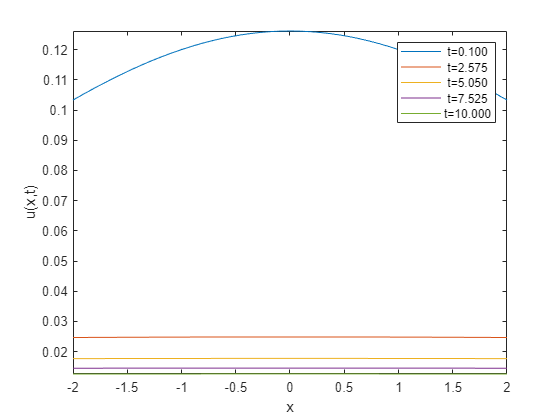

k = 0.05;
u = @(x,t)sqrt(4*pi*k.*t).^-1.*exp(-x.^2./(4*k.*t));

t_vals = linspace(0.1,10,5); %Times from 0 to 10, 5 data points 

u_x = @(x)u(x,t_vals);

figure
fplot(u_x,[-2 2])
xlabel('x')
ylabel('u(x,t)')
legendCell = cellstr(num2str(t_vals', 't=%.3f'));
legend(legendCell)